# Mobile robot simultaneous localization & mapping (SLAM)

Copyright (C) 1993-2018, by Peter I. Corke, http://www.petercorke.com

Our SLAM system requires a number of components:

- a vehicle

- a map that defines the positions of some known landmarks in the world

- a sensor, a range-bearing sensor in this case

- a SLAM filter

## Creating the vehicle model

First we define the covariance of the vehicles's odometry which reports distance travelled and change in heading angle

V = diag([0.005, 0.5*pi/180].^2);

then use this to create an instance of a `Bicycle` class

veh = Bicycle('covar', V)

 
veh = 
Bicycle object                      
  L=1, steer.max=0.5, accel.max=Inf 
  Superclass: Vehicle               
    max speed=1, dT=0.1, nhist=0    
    V=(2.5e-05, 7.61544e-05)        
    configuration: x=0, y=0, theta=0


and then add a "driver" to move it between random waypoints in a square region with dimensions from -10 to +10

veh.add_driver( RandomPath(10) );

We ask the `RandomPath` driver to drive the robot around for 1000 time steps and we can observe the popup figure window with an animated path

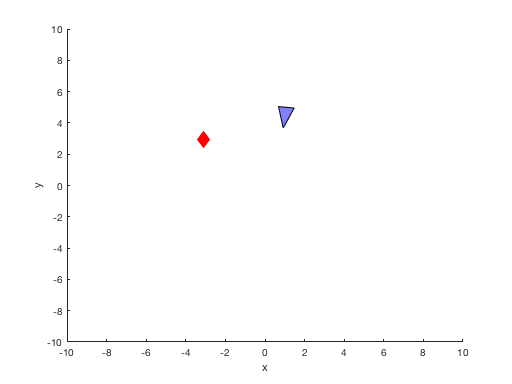

veh.run(1000);

The robot is indicated by the blue triangle and the random goal is a red diamond. Whenever the robot gets close to the goal, it changes.  The actual path followed by the robot is kept within the object `veh` and can be plotted

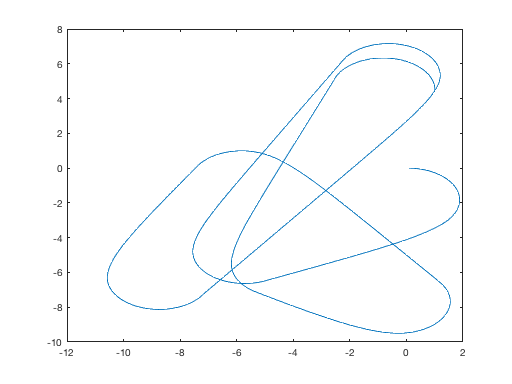

clf; veh.plot_xy()

## Creating the map

The map covers a square region with dimensions from  -10 to +10 and contains 20 randomly placed landmarks

map = LandmarkMap(20, 10)

 
map = 
LandmarkMap object
  20 landmarks    
  dimension 10.0  


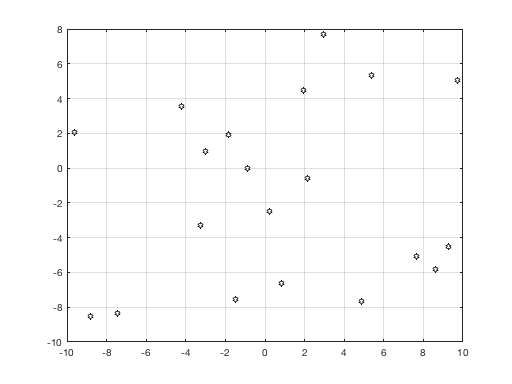

clf; plot(map)

## Creating the sensor model

We firstly define the covariance of the sensor measurements which report distance and bearing angle

W = diag([0.1, 1*pi/180].^2);

and then use this to create an instance of the `Sensor` class.

sensor = RangeBearingSensor(veh, map, 'covar', W, 'animate', 'angle', [-pi/2 pi/2], 'range', 5);

Note that the sensor is mounted on the moving robot and observes the features in the world so it is connected to the already created `Vehicle` and `Map` objects.

## Create the EKF filter

First we need to determine the initial covariance of the vehicle, this is our uncertainty about its pose (x, y, theta)

P0 = diag([0.005, 0.005, 0.001].^2);

Now we create an instance of the EKF filter class

ekf = EKF(veh, V, P0, sensor, W, []);

and connect it to the vehicle and the sensor and give estimates of the vehicle and sensor covariance (we never know this is practice).

Now we will run the filter for 1000 time steps.  At each step the vehicle moves, reports its odometry and the sensor measurements and the filter updates its estimate of the vehicle's pose

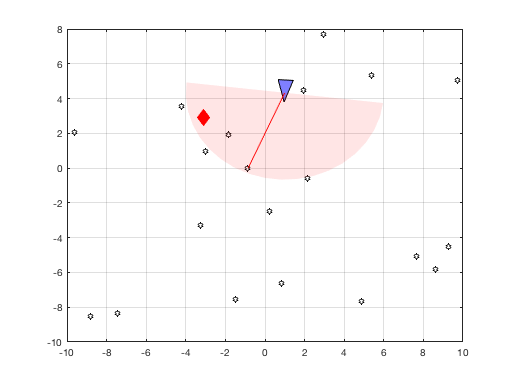

ekf.run(1000);

all the results of the simulation are stored within the `EKF` object

First let's plot the map

clf; map.plot()

and then overlay the path actually taken by the vehicle

veh.plot_xy('b');

and then overlay the path estimated by the filter

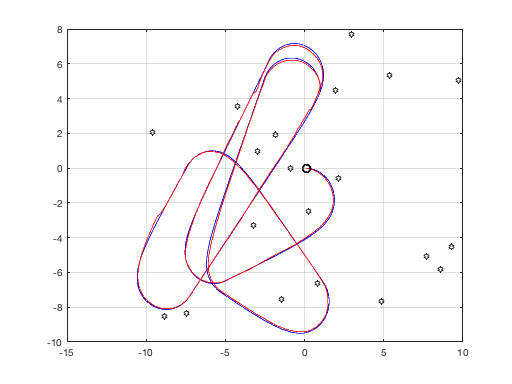

ekf.plot_xy('r');

The actual and estimated path agree quite closely.  If you zoom in on the plot you can find some areas where the match is not so good.

Now let's plot the error in estimating the pose

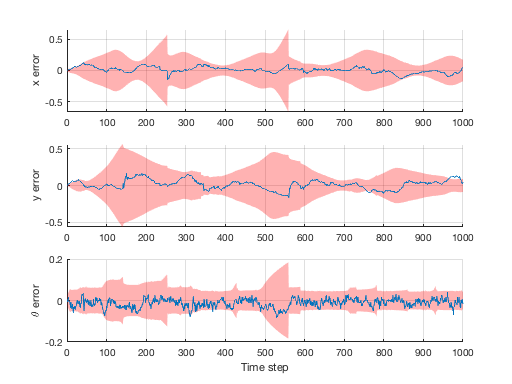

ekf.plot_error()

and this is overlaid with the estimated covariance of the error (red shape)

Remember that the SLAM filter has not only estimated the robot's pose, it has simultaneously estimated the positions of the landmarks as well.  How well did it do at that task?  We will show the landmarks in the map again

map.plot();

and this time overlay the estimated landmark (with a +) and the 95% confidence bounds as green ellipses

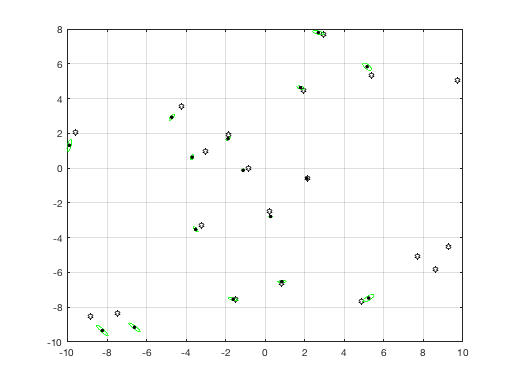

ekf.plot_map('g');

Once again, if you zoom in on the plot you can find some areas where the match is not so good.